# Question-1)

clc;
clear;

% Loading the data in matlab
data = load("1D-data.txt");

Error using load
'1D-data.txt' is not found in the current folder or on the MATLAB path, but exists in:
    C:\clemson_university\semesters\fall'22\ECE_8540_Analysis_of_Tracking_Systems\labs\lab_4

Change the MATLAB current folder or add its folder to the MATLAB path.


% Assuming the data is recorded after every 1 seconds
timeseries = [1:1:numel(data)];

% Plotting the raw data 
figure(1)
scatter(timeseries, data,'.','blue')
title('Measured Position (1D)')
xlabel('Time (in seconds)')
ylabel('Position')

dt = 1; % 1 second interval
n_states = 2; % number of state variables (position and velocity)
P = [1,dt;0,1]; % state transition matrix
M = [1,0]; % observation matrix
Q = [0 0.005
     0 0.005]; % dynamic uncertainity matrix
R = 0.01; % measurement noise covariance
S = eye(2); % initial variance
X = [data(1); 0]; % initial state
Y =  data; % measurements
X_est(:,1) = [data(1); 0]; % position estimate matrix

for i = 2:numel(data)
    %% Prediction
    X_pred = P*X; % predict next stage
    S_pred = P*S*P' + Q; % predicting state variance
    
    %% Correction
    K = S_pred*M'/((M*S_pred*M'+R));
    X = X_pred+K*(Y(i)-M*X_pred);
    S = (eye(n_states)-K*M)*S; 
    %% Storing estimation
    X_est(:,i) = X;
end

% Plotting the estimates
hold on 
scatter(timeseries,X_est(1,:),'.','red');
title('Tracking Object in 1-D')
xlabel('Time (in seconds)'); 
ylabel('Position');
legend('Measured position', 'Estimated position')
hold off

# Question-2)

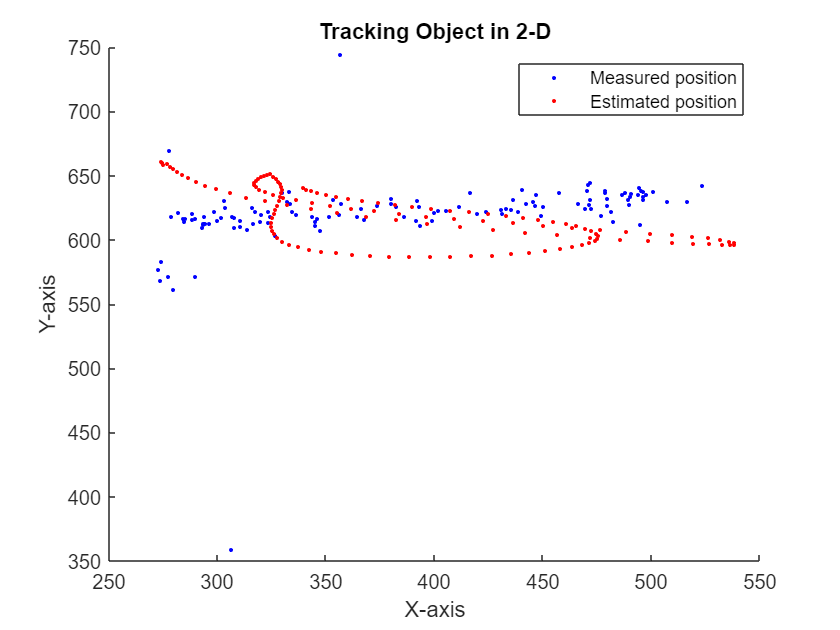

clc;
clear;

% Loading the data in matlab
data = load("2D-UWB-data.txt");
x = data(:,1); % saving x data
y = data(:,2); % saving y data

% Plotting the raw data
figure(2)
scatter(x,y,'.','blue')
title('Measured Position (2D)')
xlabel('X-axis')
ylabel('Y-axis')

dt = 1; % 1 second interval
n_states = 4; % % number of state variables (position and velocity in x&y)
P = [1 0 dt 0; % state transition matrix
     0 1 0 dt;
     0 0 1 0;
     0 0 0 1];
M = [1 0 0 0;
     0 1 0 0]; % observation matrix
Q = [0 0 0 0; % dynamic covariance matrix
     0 0 0 0;
     0 0 0 0.005;
     0 0 0.005 0]; 
R = [100 0.005; % measurement noise covariance matrix
     0.005 100]; 
S = eye(4); % initial variance]
X = [data(1,1); % initial state
     data(1,2);
     0;
     0];
Y =  data';% measurement
X_est(:,1) = X; % position estimate matrix

for i = 2:length(data)
    %% Prediction
    X_pred = P*X; % predict next stage
    S_pred = P*S*P' + Q; % predicting state variance
    
    %% Correction
    K = S_pred*M'/((M*S_pred*M'+R));
    X = X_pred+K*(Y(:,i)-M*X_pred);
    S = (eye(n_states)-K*M)*S; 
    %% Storing estimation
    X_est(:,i) = X;
end

% Plotting the estimates
hold on 
scatter(X_est(1,:),X_est(2,:),'.','red')
title('Tracking Object in 2-D')
xlabel('X-axis'); 
ylabel('Y-axis');
legend('Measured position', 'Estimated position')
hold off